% Define the constants




$$$B=B r+\mu_0 \mu_r H-E \cdot e^{-k_1 \cdot\left(k_2+H\right)}$$$


k1 is sqaureness Factor

k2 


$$$k_2=-\frac{\ln \left[\left(B r+\left(\mu_r-1\right) \cdot \mu_0 \cdot H c J\right) \cdot \frac{1}{E}\right]}{k_1}-H c J$$$


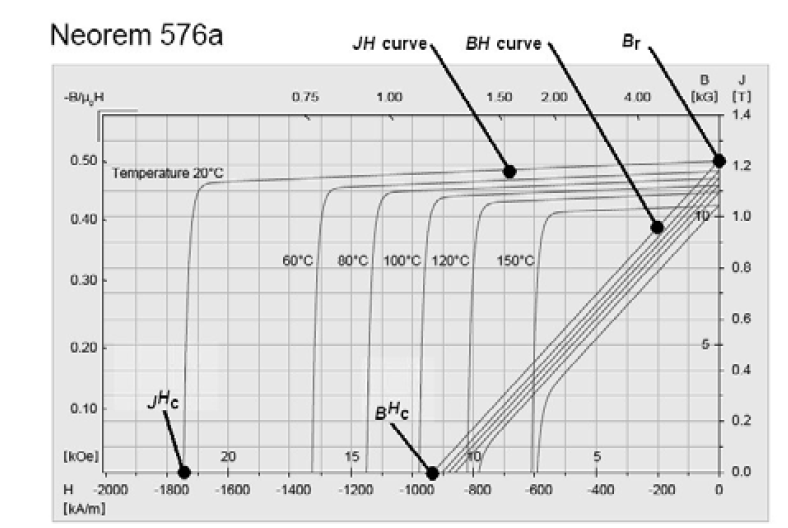

function fitResult= defNonlinearDemagnetizationModelBySami(TotalTable)


    % 주어진 데이터에서 Br과 Hcj 값을 추출
    Br = TotalTable.Bvalue(TotalTable.Hvalue == 0);
    Hcj = TotalTable.Hvalue(TotalTable.Bvalue == 0);
    
    % 주어진 데이터에서 Br과 Hcj가 아닌 나머지 값을 추출
    Bdata = TotalTable.Bvalue(~(TotalTable.Hvalue == 0 & TotalTable.Bvalue == 0));
    Hdata = TotalTable.Hvalue(~(TotalTable.Hvalue == 0 & TotalTable.Bvalue == 0));
    
    mu0 = 4 * pi * 10^-7;
    k1 = 6E-5;
    E = 1;
    
    % k2 수식 정의
    k2 = @(mu_r) -log((Br + (mu_r-1) * mu0 * Hcj) / E) / k1 - Hcj;
    
    % customEqn 정의
    customEqn = @(mu_r, H) Br + mu0 * mu_r .* H - E .* exp(-k1 .* (k2(mu_r) + H));
    
    % fit 함수 호출
    fitType = fittype(customEqn, 'independent', 'H', 'coefficients', {'mu_r'});
    opts = fitoptions(fitType);
    
    % 상한과 하한 설정
    opts.Lower = [1.042]; % mu_r의 최소값
    opts.Upper = [1.2]; % mu_r의 최대값
    opts.StartPoint = [1.042];
    
    fitResult = fit(Hdata, Bdata, fitType, opts);
end

%     % 상수 정의
%     mu0 = 4*pi*10^-7; % 진공의 투자율
%     k1 = 9.66E-5; % 주어진 값
%     E = 1; % E값 고정
% 
%     % Br과 HcJ 설정
%     Br = TotalTable.Bvalue(TotalTable.Hvalue == 0);
%     HcJ = TotalTable.Hvalue(TotalTable.Bvalue == 0);
% 
%     % k2 계산
%     k2 = @(mu_r) -log((Br + (mu_r - 1) * mu0 * HcJ) / E) / k1 - HcJ;
% 
%     % 커스텀 수식 정의
%     customEqn = @(mu_r, H) Br + mu0 * mu_r * H - E .* exp(-k1 .* (k2(mu_r) + H));
% 
%     % fit 함수 시작
%     fitType = fittype(customEqn, 'independent', 'H', 'coefficients', {'mu_r'});
%     startPoints = 1; % mu_r의 초기 추정값
% 
%     fitResult = fit(TotalTable.Hvalue, TotalTable.Bvalue, fitType, 'Start', startPoints);
% end


% function mu_r_opt = fitBHcurve(TotalTable)
%     % 상수 정의
%     mu0 = 4*pi*10^-7; % 진공의 투자율
%     k1 = 6E-5; % 주어진 값
% 
%     % Br과 HcJ 설정
%     Br = TotalTable.Bvalue(TotalTable.Hvalue == 0);
%     HcJ = TotalTable.Hvalue(TotalTable.Bvalue == 0);
% 
%     % 최적화 문제 설정
%     fun = @(x) objectiveFunction(x, Br, HcJ, mu0, k1, TotalTable.Hvalue, TotalTable.Bvalue);
%     x0 = [1, 1, 1]; % 초기 추측 값: [mu_r, E, k2]
%     lb = []; % 하한 없음
%     ub = []; % 상한 없음
%     options = optimset('Display', 'off');
% 
%     % 최적화 수행
%     x_opt = fmincon(fun, x0, [], [], [], [], lb, ub, [], options);
% 
%     % 최적의 mu_r 값 반환
%     mu_r_opt = x_opt(1);
% end
% 
% function error = objectiveFunction(x, Br, HcJ, mu0, k1, Hvalue, Bvalue)
%     mu_r = x(1);
%     E = x(2);
%     k2 = -log((Br + (mu_r - 1) * mu0 * HcJ) * (1/E))/k1 - HcJ;
% 
%     % 주어진 방정식에 따라 B값 계산
%     B_calc = Br + mu0 * mu_r * Hvalue - E .* exp(-k1 .* (k2 + Hvalue));
% 
%     % 실제 B값과 계산된 B값 간의 차이의 제곱 합
%     error = sum((Bvalue - B_calc).^2);
% end